%pre-simulate iemg data
table=readtable("../raw_data/Emg_for_fitting_DPF.xlsx");
x = table{:,1}; y = table{:,2};
[hill_a,hill_b,hill_c]=classic_hill(x,y);
data_Pcr  = readtable('../raw_data/Pcr_for_fitting_DPF.xlsx'); % Pcr force
cycle_index_exp=data_Pcr{:,1};
cycles=1:1:max(cycle_index_exp);
m=length(cycles);
T_cycles=(m+(m*0.10));
sim_iemg=zeros(T_cycles,1);
a=0;
for i=1:m
    a=((hill_a*(cycles(i)^hill_b))/(cycles(i)+hill_c))/100;
    sim_iemg(i) = a;
end
for i=m+1:T_cycles
    sim_iemg(i)=sim_iemg(m);
end

% input for  the model
load('params/solutions_SI.mat');
params = solutions(1,3).X;
cut_off=m;
H_set = 1:0.01:2;
n=length(H_set);
dpidt_set = 0;
dHdt_set = 0;
dMgADPdt_set = 0;
dPCrdt_set = 0;

% Simulate force and met profiles for different H+ accumulation
force=zeros(T_cycles,n);
Pi_lvl=zeros(T_cycles,n);
ADP_lvl=zeros(T_cycles,n);
PCr_lvl=zeros(T_cycles,n);
H_lvl=zeros(T_cycles,n);
ATP_lvl=zeros(T_cycles,n);
for i=1:n
    iemg_temp=sim_iemg;
    [Y]=eval_pH_SI(params,iemg_temp,T_cycles,m,H_set(i),dpidt_set,dHdt_set,dMgADPdt_set,dPCrdt_set);
    force(:,i)=Y(:,6);
    Pi_lvl(:,i)=Y(:,1);
    ADP_lvl(:,i)=Y(:,2);
    PCr_lvl(:,i)=Y(:,3);
    H_lvl(:,i)=Y(:,4);
    ATP_lvl(:,i)=Y(:,5);
end

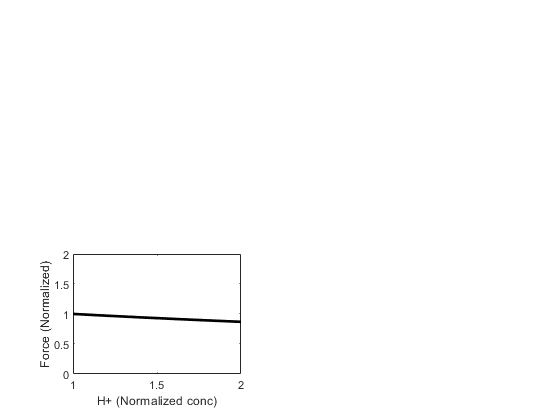

% construct figure s3c
figure(5);clf;
%scatter(H_set,force(T_cycles,:)/force(m,1),30,"black","square","filled"); hold on; box on;
plot(H_set,force(T_cycles,:)/force(m,1),'linewidth',2,'Color','k'); hold on; box on;
%xlim([0 250]);
ylim([0 2]);
xlabel('H+ (Normalized conc)');
ylabel('Force (Normalized)');
set(gca,'Unit','Inches')
p = get(gca,'Position');
set(gca,'Unit','Inches','Position',[p(1) p(2) 1.75 1.25]);
exportgraphics(figure(5),fullfile('figure_8_subplots','figure_8_d.pdf'),'BackgroundColor','w','Resolution',300,'ContentType','vector');